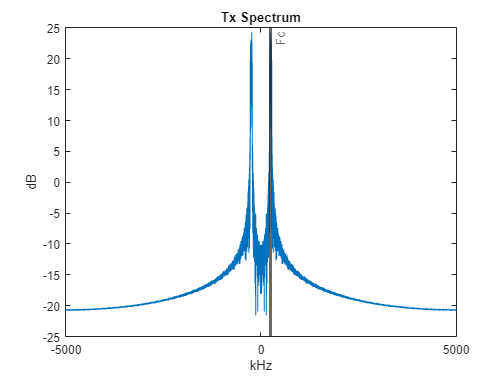

clear;clc;close all;
Fs = 50000;
Fc = 250000;
DacFs = 10000000;
Nfft = 4096;
%cp = Nfft;
M = 16;
ofdm_symbols = 16;

Factor = ceil(DacFs/Fs);
Nfft_p = 16*Nfft;
F = (-Nfft_p/2:Nfft_p/2-1)/(Nfft_p)*Fs*Factor;
F = F/1000;
Ts = 1/DacFs;
t = 0:Ts:Nfft*Factor*Ts-Ts;
data = randsrc(length(1:Nfft),1,0:M-1);
mod_data = qammod(data,M);
y = ifft(ifftshift(mod_data),Nfft).';
Y = interp(y,Factor,10,1);
Y_i = real(Y) .* cos(2*pi*Fc*t);
Y_q = imag(Y) .* -sin(2*pi*Fc*t);
Y_real = Y_i + Y_q;
figure(),plot(F,10*log10(abs(fftshift(fft(Y_real,Nfft_p))))),xlabel('kHz'),ylabel('dB'),xline([(Fc-Fs/2)/1000 Fc/1000 (Fc+Fs/2)/1000],'-',{' ','Fc',' '})
title('Tx Spectrum')

Rx = Decimate(complex(real(Y),imag(Y)),Factor);
figure(),plot(F,10*log10(abs(fftshift(fft(Rx,Nfft_p))))),xlabel('kHz'),ylabel('dB')
title('Rx Downconverted Spectrum')
